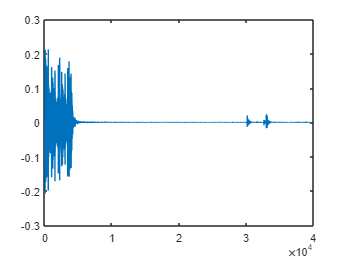

clear
load short_modem_rx.mat

% The received signal includes a bunch of samples from before the
% transmission started so we need discard these samples that occurred before
% the transmission started. 

start_idx = find_start_of_signal(y_r,x_sync);
% start_idx now contains the location in y_r where x_sync begins
% we need to offset by the length of x_sync to only include the signal
% we are interested in
y_t = y_r(start_idx+length(x_sync):end); % y_t is the signal which starts at the beginning of the transmission


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%  Put your decoder code here
%%
% Low Pass Filter
plot(y_t)

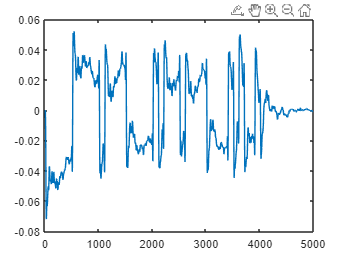

c = cos(2*pi*f_c/Fs*[0:length(y_t)-1]');
y_t = c.*y_t;
%plot(y_t)
%plot_ft_rad(y_t, Fs);
% plot_ft_rad(conv_cos, Fs);

[B, A] = butter(5, 0.1, "low"); 
filtered_signal = filter(B, A, y_t);
plot(filtered_signal)
xlim([0, 5000])

% soundsc(filtered_signal, Fs);

plus_minus_one = sign(filtered_signal(50:100:5000));

zeros_ones_signal = (plus_minus_one + 1) * 0.5;

act_signal = zeros_ones_signal(1:40);

soundsc(act_signal, Fs)

% W = 2*pi*100;
% h = W/pi*sinc(W/pi*length(y_t));
% sinc_conv = conv(y_t, h);
% plot_ft_rad(sinc_conv, Fs);
% plot(sinc_conv);

%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


% % convert to a string assuming that x_d is a vector of 1s and 0s
% % representing the decoded bits
BitsToString(act_signal)

ans = 'Hello'


% 